% Obtain the linear prediction coefficients at the center frame for 
% three cardinal vowel sounds using the first utterance of question 2. 
% Use the “lpc” function of MATLAB to compute the coefficients. 
% Obtain the LPC spectrum for three vowels at the center frame using 
% the vocal tract transfer function assuming G=1.

% Short time analysis code
clear all
close all
clc

% recording audio 
fs = 16000;
NumSeconds = 5;
NumBits_quant = 16;
Num_channels = 1; % mono 1 channel, 2 for stereo


[speech_vowels, fs] = audioread('abhishek_aiu.wav');
speech_vowels = speech_vowels(floor(0.5*fs):floor(3*fs));
a_midpoint = 0.4813; % in sec obtained from the plot
i_midpoint = 1.179;
u_midpoint = 1.915;
alpha = 0.9;

a_midpoint_sample = round(a_midpoint*fs);
i_midpoint_sample = round(i_midpoint*fs);
u_midpoint_sample = round(u_midpoint*fs);

half_wideband_windwolen = round(30*0.001*fs/2);
sig = speech_vowels(a_midpoint_sample-half_wideband_windwolen:a_midpoint_sample+half_wideband_windwolen);
sig = sig/max(abs(sig));
sig = sig(2:end) - alpha*sig(1:end-1);

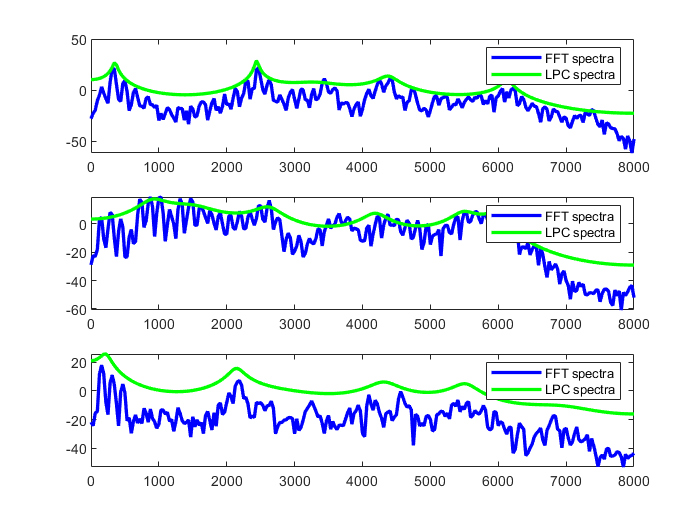


% preemphasis
lpc_a = lpc(sig, 12);
figure;subplot(3,1,1)
[H,w] = freqz(1, lpc_a, 512, 'whole'); 
spec = fft(sig.*hamming(length(sig)), 512);
freq = (0:256)*(fs/512);
plot(freq, 20*log10(abs(spec(1:257))),'b', 'LineWidth',2);
hold on
plot(freq, 20*log10(abs(H(1:257))),'g', 'LineWidth',2);
legend('FFT spectra','LPC spectra')

half_wideband_windwolen = round(30*0.001*fs/2);
sig = speech_vowels(i_midpoint_sample-half_wideband_windwolen:i_midpoint_sample+half_wideband_windwolen);
sig = sig/max(abs(sig));
sig = sig(2:end) - alpha*sig(1:end-1);

% preemphasis
lpc_a = lpc(sig, 12);
subplot(3,1,2)
[H,w] = freqz(1, lpc_a, 512, 'whole'); 
spec = fft(sig.*hamming(length(sig)), 512);
freq = (0:256)*(fs/512);
plot(freq, 20*log10(abs(spec(1:257))),'b', 'LineWidth',2);
hold on
plot(freq, 20*log10(abs(H(1:257))),'g', 'LineWidth',2);
legend('FFT spectra','LPC spectra')


half_wideband_windwolen = round(30*0.001*fs/2);
sig = speech_vowels(u_midpoint_sample-half_wideband_windwolen:u_midpoint_sample+half_wideband_windwolen);
sig = sig/max(abs(sig));
sig = sig(2:end) - alpha*sig(1:end-1);

% preemphasis
lpc_a = lpc(sig, 12);
subplot(3,1,3)
[H,w] = freqz(1, lpc_a, 512, 'whole'); 
spec = fft(sig.*hamming(length(sig)), 512);
freq = (0:256)*(fs/512);
plot(freq, 20*log10(abs(spec(1:257))),'b', 'LineWidth',2);
hold on
plot(freq, 20*log10(abs(H(1:257))),'g', 'LineWidth',2);
legend('FFT spectra','LPC spectra')

temp=1;
